format long eng;
kbr1b_x = importdata("KBR1B_2020-09-28_Y_04.txt");
gni1b_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni1b_b = importdata("GNI1B_2020-09-28_D_04.txt");
sca1b_a = importdata("SCA1B_2020-09-28_C_04.txt");
sca1b_b = importdata("SCA1B_2020-09-28_D_04.txt");
acc1b_a = importdata("ACT1B_2020-09-28_C_04.txt");
acc1b_b = importdata("ACT1B_2020-09-28_D_04.txt");

los = gni1b_b.data(:, 1: 3) - gni1b_a.data(:, 1: 3);
dis = sqrt(sum(los.^2, 2));
los = los ./ dis;
rotm_a = zeros(17280, 3, 3);
rotm_b = zeros(17280, 3, 3);
eqa = zeros(17280, 6);
eqb = kbr1b_x(:, 2) - dis(1: 5: end);

for i = 1: 17280
    eqa(i, 1: 3) = los(i*5-4, :) * quat2rotm(sca1b_a.data(i*5-4, 2: 5));
    eqa(i, 4: 6) = los(i*5-4, :) * quat2rotm(sca1b_b.data(i*5-4, 2: 5));
end
eqa(:, 1: 3) = -eqa(:, 1: 3);
diff_eqa = diff(eqa, 1);
% 10522: 11121
% 3695: 4284
% 3695: 4284
% 5972: 6571

diff2_eqa = diff(diff_eqa, 1);
diff3_eqa = diff(diff2_eqa, 1);
diff_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end));
diff2_eqb = diff(kbr1b_x(:, 2) - dis(1: 5: end), 2);
diff3_eqb = diff(diff2_eqb);
diff2_eqb = filter_pdfree(Num, diff2_eqb);
diff2_eqa = filter_pdfree(Num, diff2_eqa);
diff3_eqa = filter_pdfree(Num, diff3_eqa);
diff3_eqb = filter_pdfree(Num, diff3_eqb);
% fft_diff3_eqb = fft(diff3_eqb(10522: 11021));
% fft_diff3_eqa = [fft(diff3_eqa(10522: 11021, 4)), fft(diff3_eqa(10522: 11021, 5))];
% eqb = [fft_diff3_eqb(11); fft_diff3_eqb(21)];
% eqa = [fft_diff3_eqa(11, :); fft_diff3_eqa(21, :)];
% eqa_real = real(eqa);
% eqa_imag = imag(eqa);
% eqb_real = real(eqb);
% eqb_imag = imag(eqb);
% 
% eqa_abs = abs(eqa);
% eqa_ang = angle(eqa);
% eqb_abs = abs(eqb);
% eqb_ang = angle(eqb);
lsqr(diff3_eqa(5972: 6571, [2 3 5 6]), diff3_eqb(5972: 6571) - diff3_eqa(5972: 6571, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.99。


ans =     1.50863707357256e-003
   -49.3285068158284e-003
    29.5801634431948e-003
   -69.7031957455556e-006


lsqr(diff3_eqa(3695: 4284, [2 3 5 6]), diff3_eqb(3695: 4284) - diff3_eqa(3695: 4284, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.91。


ans =     2.53767379926829e-003
   -42.9343741974282e-003
   -121.843416815248e-006
    2.60168453687708e-003


lsqr(diff3_eqa(8256: 8855, [2 3 5 6]), diff3_eqb(8256: 8855) - diff3_eqa(8256: 8855, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.87。


ans =    -21.9154053225179e-003
    5.06284700213425e-003
   -1.40792962023656e-003
   -30.9331103111578e-003


lsqr(diff3_eqa(10522: 11121, [2 3 5 6]), diff3_eqb(10522: 11121) - diff3_eqa(10522: 11121, [1 4])*[1.444; 1.444])

lsqr 在 迭代 4 停止，而没有收敛到所需容差 1e-06，
这是因为已达到最大迭代数。
迭代返回的 (数目 4) 的相对残差为 0.85。


ans =    -4.54544194245089e-003
    51.9152066632049e-003
    1.68384812115479e-003
    71.0313316978716e-003


solver_spectral(diff2_eqa(3695: 4284, :), diff2_eqb(3695: 4284), [4 6], 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.011。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.012。


ans =     382.732110866655e-009   -11.0590863798743e-006
    193.378145166304e-009    8.35113211693564e-009


lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。


ans =     584.607663779988e-009
    272.355060752230e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 2.4e-09。


ans =    -2.88834851192299e-003


solver_spectral(diff3_eqa(3695: 4284, :), diff3_eqb(3695: 4284), [4 6], 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.027。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.036。


ans =     48.0577137542249e-009   -1.38854415657769e-006
    48.4573716898026e-009    2.47798572106405e-009


lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.031。


ans =     73.3665617670187e-009
    68.2900356096843e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 6.9e-11。


ans =    -2.85999050667981e-003


solver_spectral(diff2_eqa(5972: 6571, :), diff2_eqb(5972: 6571), [4 6], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.012。


ans =     391.140969473019e-009   -11.0640303835322e-006
    193.714443467621e-009    8.07287973364625e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.031。


ans =     567.798435782402e-009
    271.759208739250e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.9e-09。


ans =    -270.324263372854e-006


solver_spectral(diff3_eqa(10522: 11121, :), diff3_eqb(10522: 11121), [4 5], 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.034。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.05。


ans =     48.0187233137600e-009   -1.39134433815566e-006
    48.7639937779397e-009    12.3840266741265e-009


lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.06。


ans =     71.9880151878696e-009
    72.1741507017666e-009


lsqr 在解的 迭代 2 处收敛，并且相对残差为 1.8e-11。


ans =    -1.90389873315727e-003


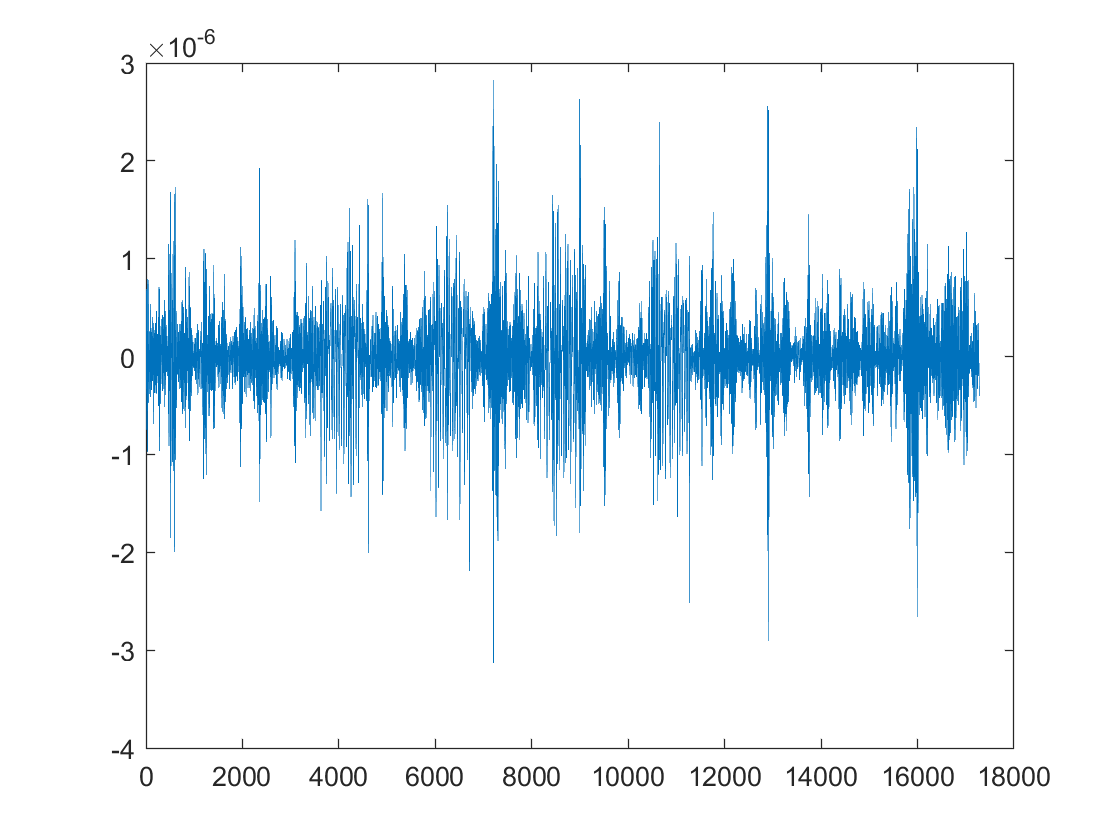

acc_grav = importdata("..//..//temp//acc_grav_calibra2.txt");
acc_grav = acc_grav(86401: end, :);
%vel_grac = cumtrapz(acc_grav, 1);
acc_grav_rela = [acc_grav(:, 1) - acc_grav(:, 4), acc_grav(:, 2) - acc_grav(:, 5), acc_grav(:, 3) - acc_grav(:, 6)];
%vel_grav_rela = [vel_grav(:, 1) - vel_grav(:, 4), vel_grav(:, 2) - vel_grav(:, 5), vel_grav(:, 3) - vel_grav(:, 6)];
gnv_a = importdata("GNV1B_2020-09-28_C_04.txt");
gnv_b = importdata("GNV1B_2020-09-28_D_04.txt");
gni_a = importdata("GNI1B_2020-09-28_C_04.txt");
gni_b = importdata("GNI1B_2020-09-28_D_04.txt");
kbr_x = importdata("KBR1B_2020-09-28_Y_04.txt");
acc_a = importdata("ACT1B_2020-09-28_C_04.txt");
acc_b = importdata("ACT1B_2020-09-28_D_04.txt");
range_acc = kbr_x(:, 4);

pos_rela = gnv_a.data(:, 1: 3) - gnv_b.data(:, 1: 3);
pos_rela_i = gni_a.data(:, 1: 3) - gni_b.data(:, 1: 3);
los = pos_rela ./ sqrt(sum(pos_rela.^2, 2));
los_i = pos_rela_i ./ sqrt(sum(pos_rela_i.^2, 2));
vel_rela = gni_a.data(:, 7: 9) - gni_b.data(:, 7: 9);
los_vec = vel_rela ./ sqrt(sum(pos_rela.^2, 2)) - pos_rela_i .* dot(los_i, vel_rela, 2) ./ sum(pos_rela.^2, 2);

range_acc_grav = zeros(length(los), 1);
for i = 1: length(range_acc_grav)
    range_acc_grav(i) = dot(acc_grav_rela(i, :), los(i, :)) + dot(vel_rela(i, :), los_vec(i, :));
end
range_acc_grav = range_acc_grav(1: 5: length(range_acc_grav));
range_acc_res = range_acc - range_acc_grav;
figure; plot(range_acc_res)

a1 = spectral_component(filter_pdfree(Num, range_acc_res(3695: 4284)), 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.6。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.6。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.6。


a1 =     583.058043781694e-009
    248.103519849738e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(3695: 4284, 4)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。


a2 =     383.355521278336e-009
    194.417212791604e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(3695: 4284, 6)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.13。


a3 =     11.0727492099179e-006
    7.80180497160358e-009


-(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =    -2.64769709391896e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(5972: 6571)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.63。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.63。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.63。


a1 =     563.342203523689e-009
    386.452064788436e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(5972: 6571, 4)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a2 =     391.568687634152e-009
    194.788555557654e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(5972: 6571, 6)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a3 =     11.0795354313242e-006
    5.13848638787657e-009


(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =    -204.171385040606e-006


a1 = spectral_component(filter_pdfree(Num, range_acc_res(8256: 8855)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.75。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.75。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.75。


a1 =     585.736465424478e-009
    233.088937822577e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8256: 8855, 4)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a2 =     390.534249665271e-009
    193.019114059829e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(8256: 8855, 5)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a3 =     11.0750035014035e-006
    54.0809089966261e-009


-(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =    -1.95271626648827e-003


a1 = spectral_component(filter_pdfree(Num, range_acc_res(10522: 11121)), 0.2)

lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.68。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.68。
lsqr 在解的 迭代 1 处收敛，并且相对残差为 0.68。


a1 =     583.716783820281e-009
    247.452267835872e-009


a2 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10522: 10821, 4)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.12。


a2 =     381.297871580270e-009
    194.069140329639e-009


a3 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10822: 11121, 4)) / 25, 0.2)

lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.1。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.1。
lsqr 在解的 迭代 4 处收敛，并且相对残差为 0.1。


a3 =     384.122259280228e-009
    196.833392341102e-009


a3(1) - a2(1)

ans =     2.82438769995854e-009


a4 = spectral_component(filter_pdfree(second_order_diff(60, 30), eqa(10522: 11121, 5)) / 25, 0.2)

lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。
lsqr 在解的 迭代 3 处收敛，并且相对残差为 0.12。


a4 =     11.0942940349876e-006
    52.4754829460073e-009


(a1(1) - 1.4444575 * a2(1)) / a3(1)

ans =     85.7753298230160e-003
